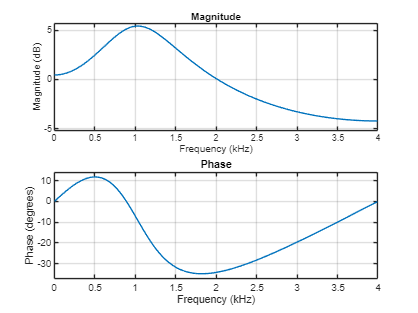

% Signal Generation and Frequency Response Analysis
% -------------------------------------------------
% This script generates various signals and plots their frequency responses 
% using the freqz function.

% Define the sampling frequency
fs = 8000;

% Define the time index for 512 samples
n = 0:511;

% Generate and plot the frequency response of the first signal
x1 = (2/3) .^ n .* cos(n*pi/4) .* [ones(1, 31) zeros(1, 512-31)];
figure(1);
freqz(x1, 1, 512, fs);

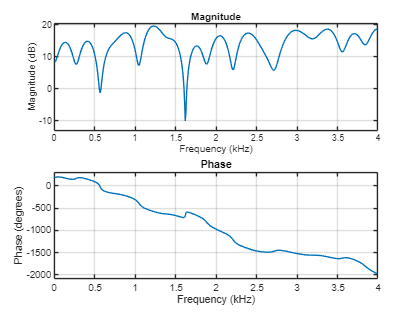


% Generate and plot the frequency response of a random signal
x2 = randn(1, 32);
figure(2);
freqz(x2, 1, 512, fs);

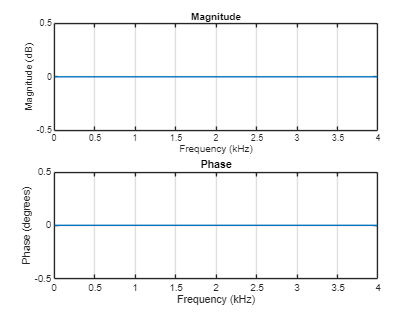


% Generate and plot the frequency response of an impulse signal
x3 = [1 zeros(1, 31)];
figure(3);
freqz(x3, 1, 512, fs);

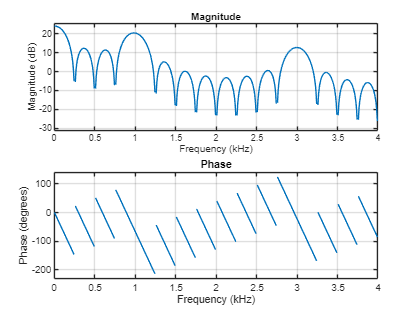


% Generate a square wave and modify it for the next signal
t = 0:31;
x = square(2*pi*t/8, 50);
for i = 1:32
    if x(i) == -1
        x(i) = 0;
    end
end

% Plot the frequency response of the modified square wave
figure(4);
freqz(x, 1, 512, fs);

b = [ 0.0947 0.2841 0.2841 0.0947];
a = [1.0000 -0.7130 0.6287 -0.1581];
[x, Fs] = audioread('_tononoise8mono.wav');
tononoise8mono = filter(b, a, x);

% Plotting
figure;

subplot(2, 1, 1);
specgram(x, 512, Fs, hanning(256), 128);
title("Original Sound");

subplot(212);
specgram(tononoise8mono, 512, Fs, hanning(256), 128); title("Filtered Sound");
sgtitle('Spectrogram of Filtered Audio Signal');

% Frequency Response Analysis of Different Systems
% ------------------------------------------------
% This script defines the coefficients for three different digital filters and
% plots their frequency responses using the freqz function.

% Define the sampling frequency
fs = 8000;

% Define coefficients and plot frequency response for System 1
b1 = 1;
a1 = [1 -0.9 -0.36];
figure(1);
freqz(b1, a1, 512, fs);

% Define coefficients and plot frequency response for System 2
a2 = [1 -0.8 0.25];
figure(2);
freqz(b1, a2, 512, fs);

% Define coefficients and plot frequency response for System 3
a3 = [1 -1.4 1.13];
figure(3);
freqz(b1, a3, 512, fs);

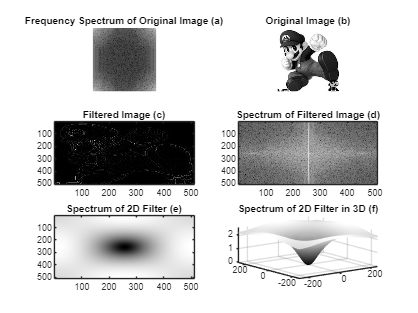

% Image Processing and Frequency Spectrum Analysis
% ------------------------------------------------
% This script performs image processing and frequency spectrum analysis.
% It reads an image, resizes it, applies a filter, and visualizes the original
% and filtered images along with their frequency spectra. The spectra of the 
% 2D filter and its 3D mesh representation are also displayed.

% Define the filter kernel
h = [-1 -1 -1; -1 8 -1; -1 -1 -1];

% Read and resize the image
figure;
%orig = imread('_mapped_gray.jpg');
orig = imread('grey_mario.jpg');
orig = imresize(orig, [512 512]);

% Ensure image is 2D (grayscale)
if size(orig, 3) == 3
    orig = rgb2gray(orig);
end

% Display the original image
subplot(3, 2, 2);
imshow(orig);
title("Original Image (b)");

% Compute and display the frequency spectrum of the original image
orig_spec = fft2(orig);
orig_spec = log(1 + abs(orig_spec));
subplot(3, 2, 1);
imshow(orig_spec, []);
title("Frequency Spectrum of Original Image (a)");

% Apply the filter to the image and display the filtered image
filtered = filter2(h, orig);
filtered = uint8(filtered);
subplot(3, 2, 3);
imagesc(filtered);
colormap(subplot(3, 2, 3), gray(256));
title("Filtered Image (c)");

% Compute and display the frequency spectrum of the filtered image
filtered_spec = fft2(filtered);
filtered_spec = log(1 + abs(filtered_spec));
filtered_spec = fftshift(filtered_spec);
subplot(3, 2, 4);
imagesc(filtered_spec);
colormap(subplot(3, 2, 4), gray(256));
title("Spectrum of Filtered Image (d)");

% Compute and display the frequency spectrum of the 2D filter
filter_spec = fft2(h, 512, 512);
filter_spec = log(1 + abs(filter_spec));
filter_spec = fftshift(filter_spec);
subplot(3, 2, 5);
imagesc(filter_spec);
colormap(subplot(3, 2, 5), gray(256));
title("Spectrum of 2D Filter (e)");

% Display the 3D mesh representation of the filter's frequency spectrum
ran = -256:255;
subplot(3, 2, 6);
mesh(ran, ran, filter_spec);
colormap(subplot(3, 2, 6), gray(256));
title("Spectrum of 2D Filter in 3D (f)");